# Battery Electric Vehicle Model

Copyright 2022 - 2023 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:open('ElectricVehicleDesignOverview.mlx')).

## Plant Model Overview

This document gives you an overview of the different components and subsystems of the battery electric vehicle (BEV) plant model. The plant model is a coupled electro-thermal model that you can use to simulate a front wheel drive (FWD) or an all wheel drive (AWD) powertrain.

Open the `BEVplantModel` model.

 
disp('Start battery electric vehicle model simulation');

Start battery electric vehicle model simulation


open_system("BEVplantModel")

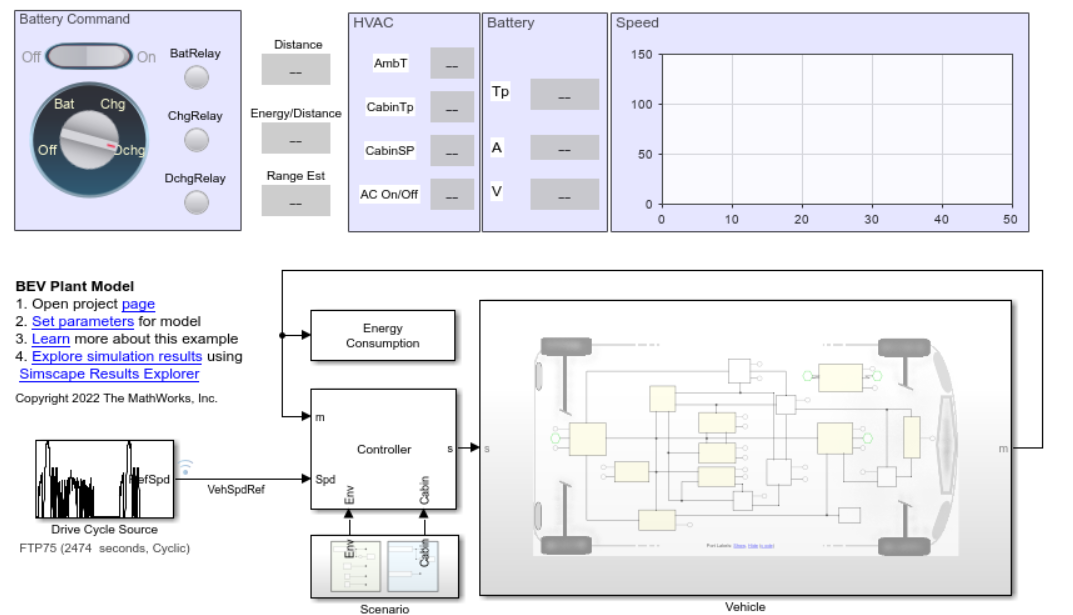

The model represents an electric vehicle platform with two electric motors, one in front (the main drive) and one in rear (for boost and all wheel drive modes). The coolant circuit maintains the temperature of the Emotors and battery within an operable range. An electric heater, in the coolant circuit, increases the battery temperature during startup in low temperature conditions. The model includes cabin heating and air conditioning as well as auxiliary loads so that you can estimate the total load on the battery load more accurately.

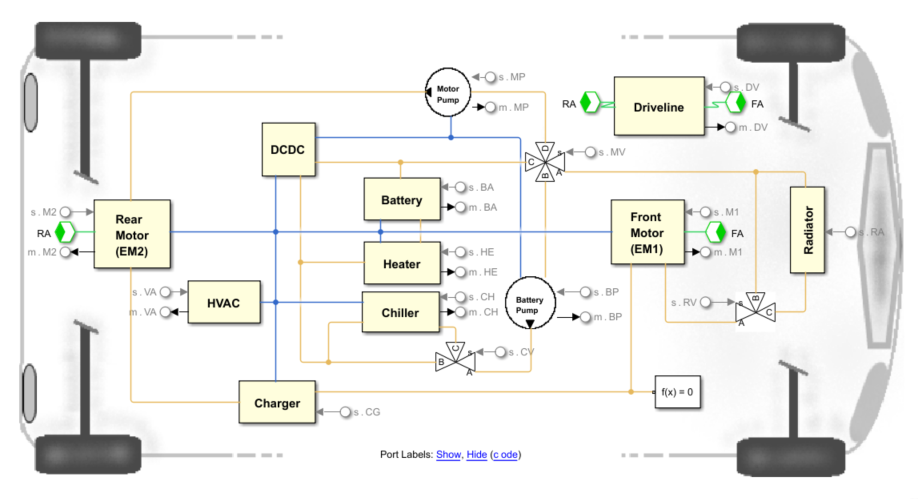

## Battery Subsystem

The battery pack is modeled using Simscape Battery™ and the Pack subsystem is modeled using the Battery Pack Builder.

To open the battery module subsystem, navigate to ***BEVplantModel/Vehicle/Battery.***

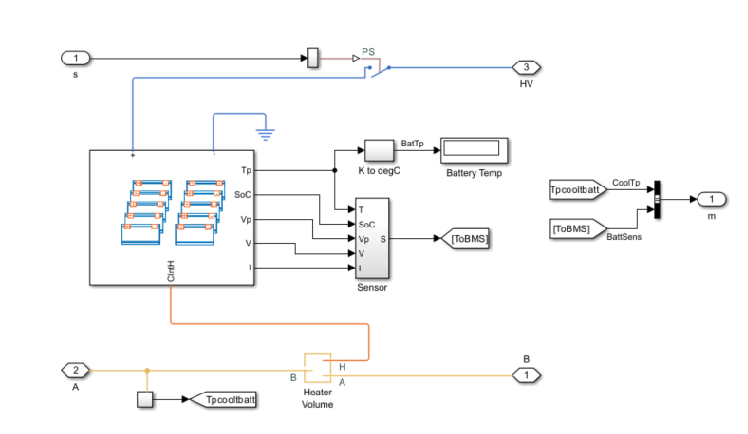

The battery comprises a battery pack of 400 V because 400 V is generally used in electric vehicles. Multiple cells are connected in series and parallel, because a single cell cannot provide a voltage this high. The battery pack comprises 10 modules, each with 11 series-connected parallel sets (p-sets). Each p-set comprises three cells in series. All modules are connected in series to form a pack of 330 cells. The power of the battery pack is 40 kWh and the charge is 100 Ah.

For more information on how to create the module used in this battery pack, see the [**Build Model of Battery Module With Thermal Effects**](docid:battery_ug#example-batt_build_battery_module_thermal_effeects) example.

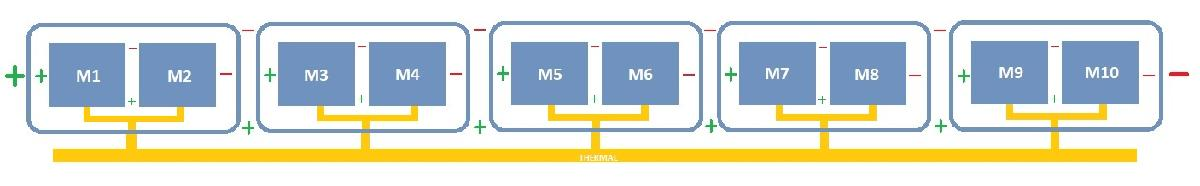

To open the battery pack subsystem, navigate to ***BEVplantModel/Vehicle/Battery/Pack.***

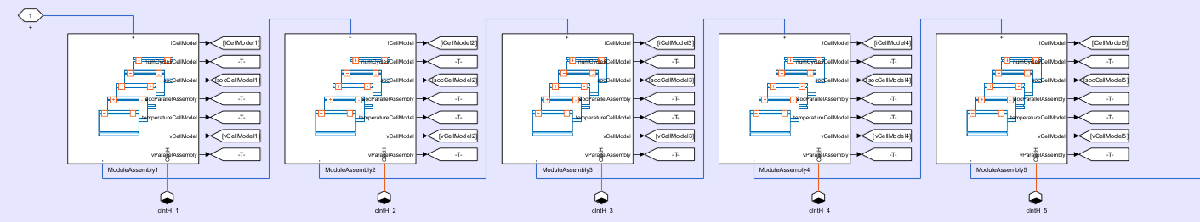

The battery management system (BMS) manages all the battery operations and keeps it within operational limits. The BMS maintains the current, voltage, and temperature of the pack within safe limits during the charging and discharging operations. In this example, the BMS controls the circuit breakers to protect the battery pack based on the pack sensor data and on estimated parameters such as the state-of charge (SOC) and the discharge and charge current limits. 

To open the BMS subsystem, navigate to ***BEVplantModel/Controller/BMS.***

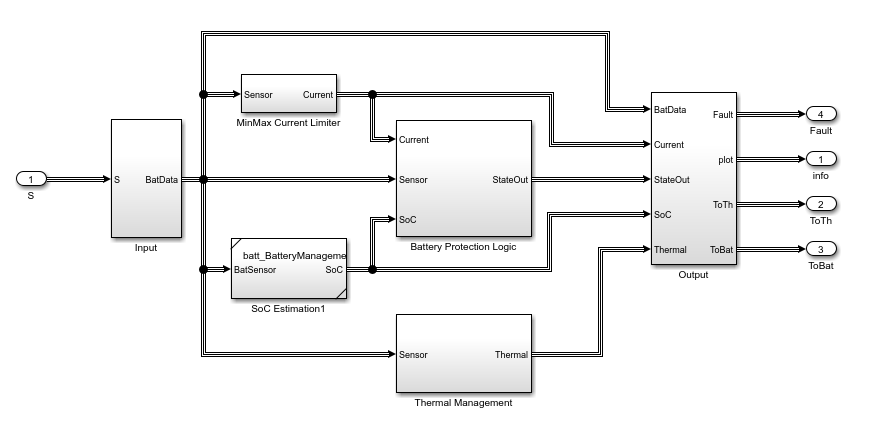

The BMS in this example comprises four different components: SOC estimation, MinMax Current Limiter, Thermal Management, and Battery Protection Logic.

## Mode Control Dashboard

In an electric vehicle, you can control the charging and discharging operations of the battery.

- When you turn the key to start the car, you connect the battery circuit breakers and connect the battery to the rest of the circuit.

- While driving, the battery is in discharge mode.

- When you connect the car to a charger, the battery is in charging mode.

In a car, the discharging and charging modes are mutually exclusive. This example emulates this scenario by implementing a charging control dashboard in the model, called Battery Command. This dashboard comprises a rotary switch for manual operations, an on-off switch for automatic operations, and indication lamps. 

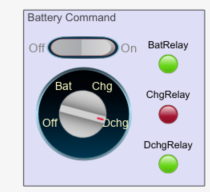

Use the rotary switch to choose between the charging and discharging modes manually. The position of the rotary switch affects the battery mode:

- **Off** — The battery is disconnected.

- **Bat** — The battery is connected.

- **Chg** — The battery is charging.

- **Dchg** —  The battery is discharging.

Use the on-off switch to switch between modes automatically by setting the switch to On and by specifying the `BatCmd` variable. When the BatCmd variable is equal to:

- **0** — The battery is disconnected.

- **1** — The battery is connected.

- **2** — The battery is charging.

- **3** — The battery is discharging.

The indication lamps show which mode the battery is currently operating in. When the lamps are red, the relevant mode is off. When the lamps are green, the relevant mode is on.

## Electric Drivetrain (e-axle)

The Front Motor (EM1) and Rear Motor (EM2) blocks model the electric drive for this system, The model has two electric motors, one connected to the front axle and one connected to the rear axle.

To open the electric motor (Emotor) subsystems, navigate to ***BEVplantModel/Vehicle/Rear Motor (EM2)***  and ***BEVplantModel/Vehicle/Front Motor (EM1).***

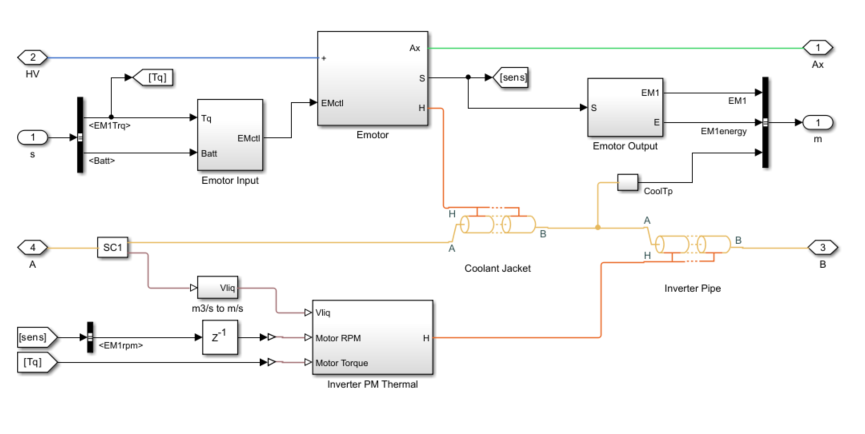

The Emotors are connected to the battery high voltage bus. The Emotors are connected or disconnected from the battery based on a relay signal from the BMS which is connected to the fault port of the Motor & Drive block.

The plant model  tracks a torque demand generated by the vehicle controller in close loop to reach a speed setpoint. You can load tabulated data of the speed and time to track a speed profile. This tabulated profile can be a standard drive cycle in the Drive Cycle Source block or real drive cycle data from test runs. Output from the Emotor block goes to a gearbox and then to the wheel. The signals are passed to other components via Simscape bus.

To open the Emotor plant subsystem, navigate to ***BEVplantModel/Vehicle/Front Motor (EM1)/Emotor.***

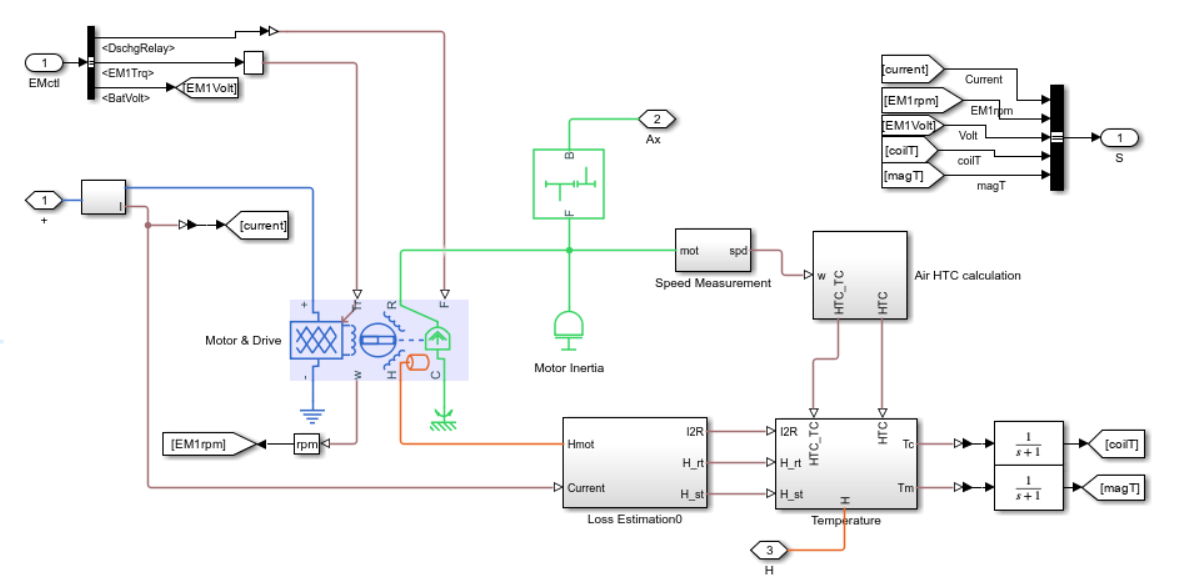 

To learn how you can generate the Emotor loss map, see the [PMSM Thermal Test Bench for Battery Electric Vehicle](matlab:open('PMSMmotorTestBench.mlx')) example.

## **Vehicle Wheels and Braking**

The vehicle model is a two axle system with two tires on each axle. Disc brakes are modeled in rear wheel for mechanical braking. The braking force comes through the Emotor for the front. The total weight of the vehicle is the combined weight of the vehicle body and the battery.

To open the driveline subsystem, navigate to ***BEVplantModel/Vehicle/Driveline.***

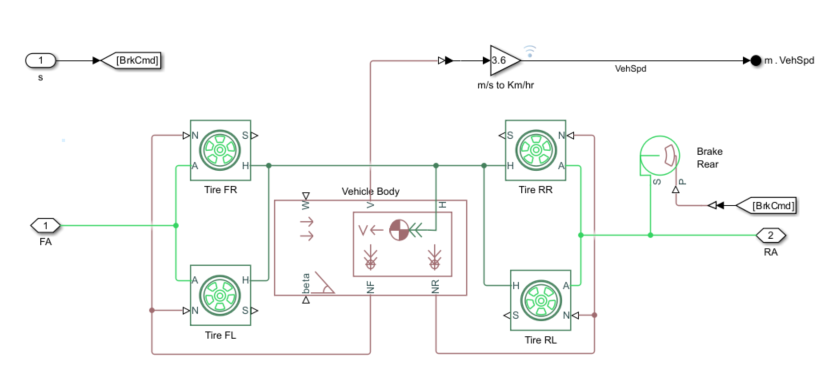

Driver control generates the torque demand for the Emotor to track a vehicle speed setpoint in closed loop. The Drive Cycle Source block is used for speed setpoint data and speed output from the Emotor plant model is fedback to the controller. The cell temperature and open circuit voltage of the cell determine the maximum threshold for charging and discharging torque. The VehicleControl block calculates the break force for the disc brake for any extra torque which is not regenrated by the emotor.

To open the vehicle control subsystem, navigate to ***BEVplantModel/Controller/VehicleControl.***

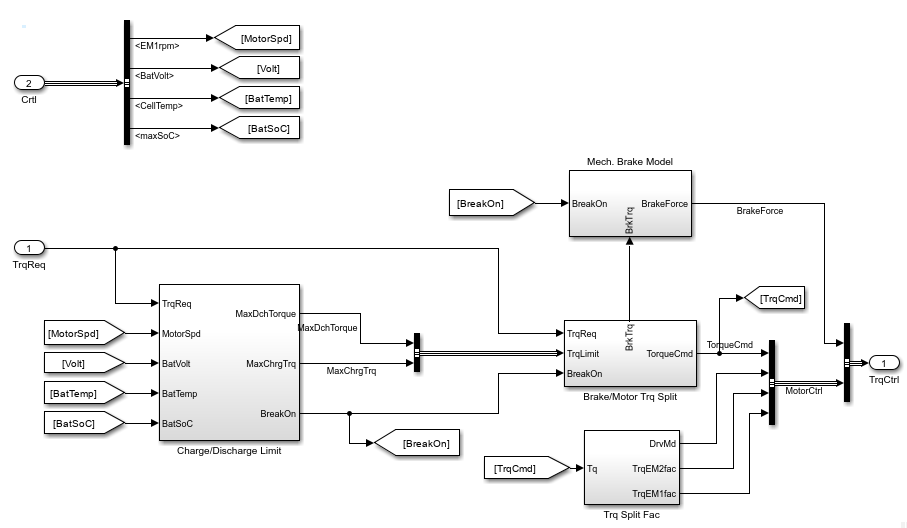

## Vehicle Thermal Management

The temperature of the components in a vehicle effects both efficiency and safety. The battery for example, has an optimal range of temperature in which the battery performance is most efficient. Extreme temperatures permanently damage the battery. You design a thermal coolant circuit to extract the extra heat from these critical components .

Ethylene glycol is the coolant fluid circulating through the component. The thermal circuit has two pumps, one for battery cooling and one for Emotor cooling. Valves control the direction of flow in the coolant loop. Air comes through the front grill over the radiator because of vehicle motion and assisted by a fan, it dumps the heat absorbed from the components to the environment.

There are two modes for the coolant flow:

- **    Parallel mode —** the  Emotor coolant loop and battery coolant loop are in parallel.

- **    Serial mode —** the coolant flows in series through all the components.

 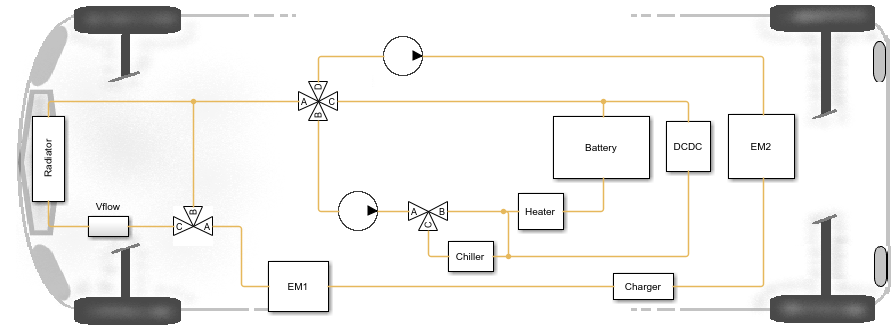

To open the chiller subsystem, navigate to ***BEVplantModel/Vehicle/Chiller.***

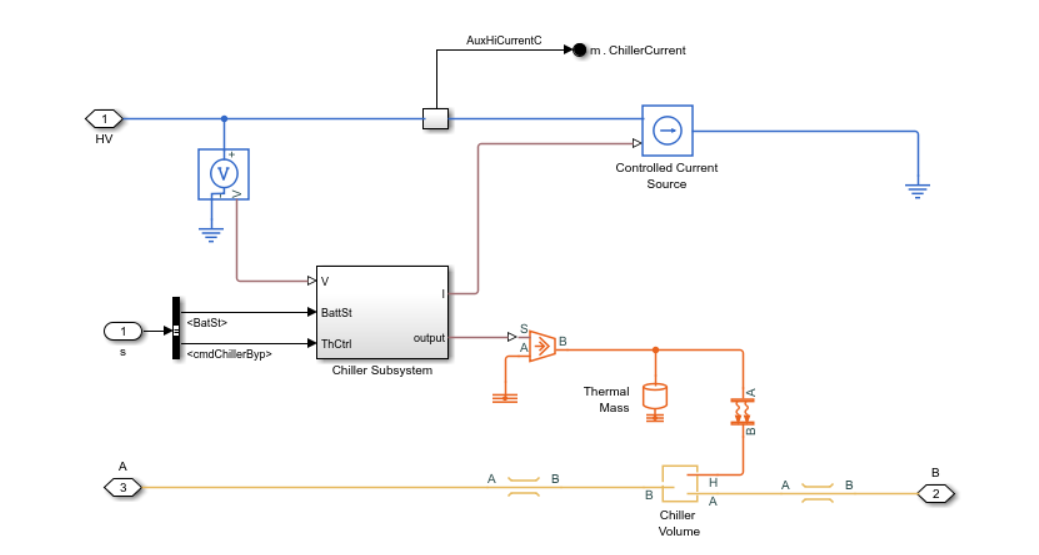

The chiller extracts a fixed amount of heat from the coolant.

To open the battery heater subsystem, navigate to ***BEVplantModel/Vehicle/Heater.***

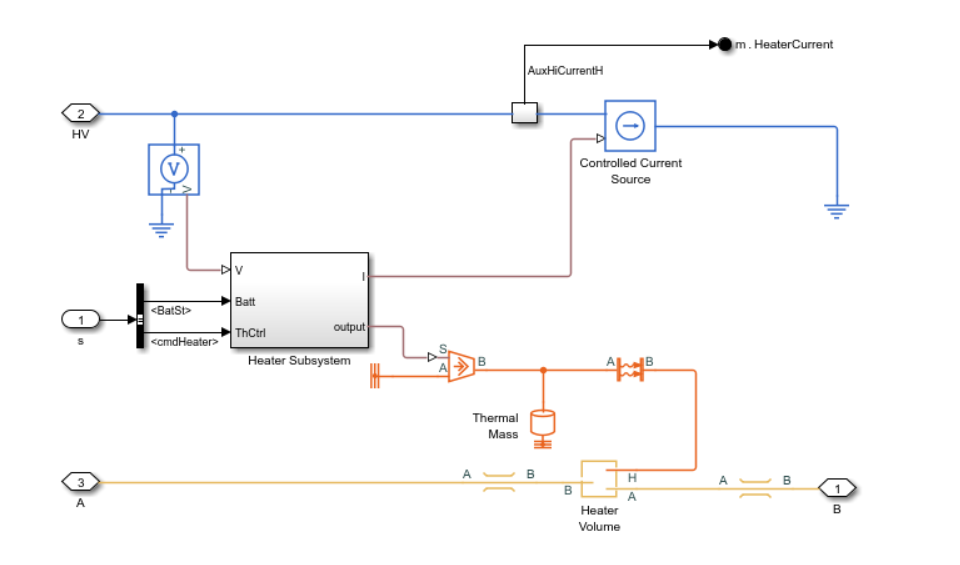

The heater adds a fixed amount of heat to the coolant in the circuit.

When the temperature of the coolant in the Emotor is low, then the coolant bypasses the radiator and keeps recirculating to increase the temperature. If the temperature is above a threshold value, coolant passes through the radiator. Similarly, when the battery temperature is above a threshold value the coolant passes through the chiller to cool the battery quickly.

A positive temperature coefficient (PTC) heater increases the temperature of the battery in low ambient temperature conditions. Once the battery temperature is high, the heater is switched off as the battery can sustain the temperature.

To open the thermal control model, navigate to ***BEVplantModel/Controller/ThermalControl.***

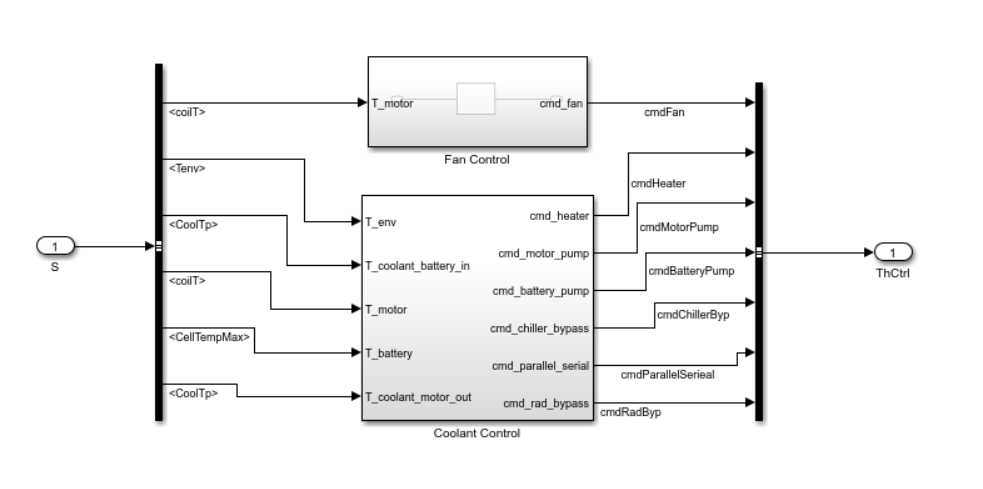

## Cabin HVAC

The battery powers heating, cooling and ventilation (HVAC) of the cabin. In near zero ambient temperature conditions, heating the cabin consumes 10-15% of the battery capacity.

The PTC heater, cooler and the blower are in loop. The blower circulates the air from the vent through the cabin to heat or cool the cabin.

To open the cabin model, navigate to ***BEVplantModel/Vehicle/HVAC/HVAC/HVACPlant.***

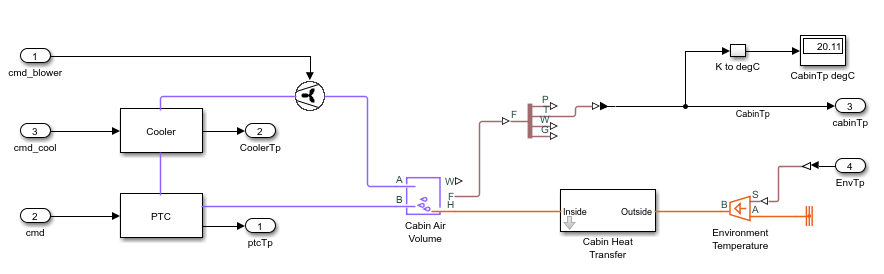

The cabin loses heat to the environment through the vehicle door, windows and roof.

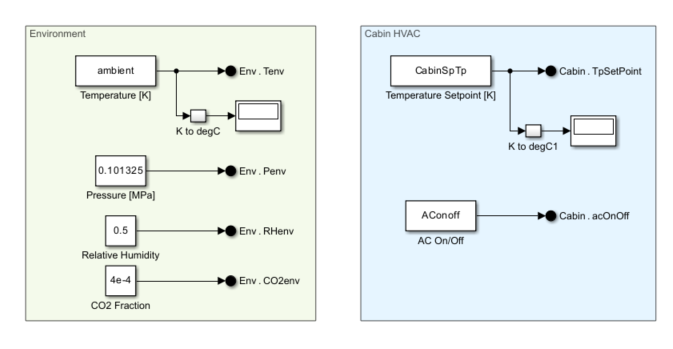

The cabin setpoint temperature and the AC on/off control is set in the Scenarios subsystem and the HVAC controller modulates the air flow in the cabin through the vent. The power required for the heater and cooler is taken out from the main battery high voltage bus.

To open the HVAC control subsystem, navigate to ***BEVplantModel/Vehicle/HVAC/Cabin/HVACcontrol.***

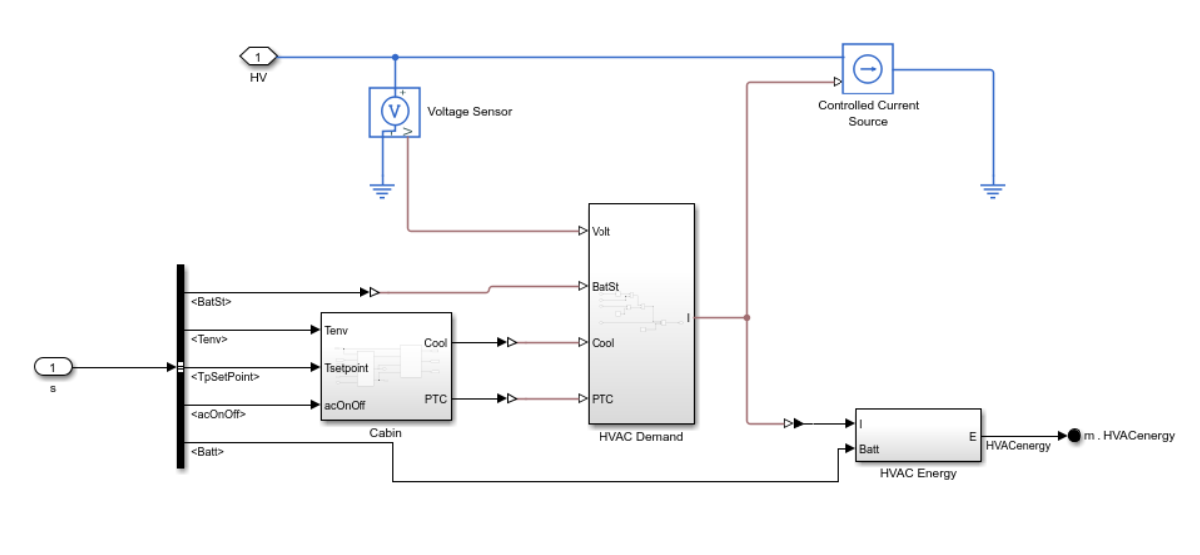

## Useful Links

[Electric Vehicle Design with Simscape](matlab:open('ElectricVehicleDesignOverview.mlx'))